%Gruppe A
%Calculate and Plot Efficiency of lawnmowing variations

% Get mower trajectory from simulation logs
trajLog = out.logsout{1}.Values;
posX = trajLog.Data(:,1);
posY = trajLog.Data(:,2);
tracePoints = [posX, posY];

% Define mowing region with only valid points inside garden
zone = garden;
insideZone = isinterior(zone, posX, posY);
traceInside = tracePoints(insideZone, :);

% Throttle point density to improve performance
fprintf('Throttle point density to improve performance');

Throttle point density to improve performance

% stride = 2;
stride = 40;
traceInside_orig = traceInside;
traceInside = traceInside(1:stride:end, :);


% Physical width of the cutting blade [meters]
BladeWidth = 0.20;

% Simulate covered area by sweeping the trace line
fprintf('Simulate covered area by sweeping the trace line');

Simulate covered area by sweeping the trace line

bufferSuccess = true;
try
    sweptArea = polybuffer(traceInside, 'lines', BladeWidth / 2);
catch
    bufferSuccess = false;
    sweptArea = polyshape();  % fallback empty polygon
end

% Calculate mowed area and efficiency
fprintf('Calculate mowed area and efficiency');

Calculate mowed area and efficiency

covered = intersect(sweptArea, zone);
A_covered = area(covered);
A_total = area(zone);
eta = (A_covered / A_total) * 100;

% Report Results
fprintf('Report Results');

Report Results

fprintf('Model: %s\n', model_name);

Model: task_gruppeC


fprintf('stop_time: %.2f\n', stop_time);

stop_time: 6000.00


fprintf('Total area of garden: %.2f m²\n', A_total);

Total area of garden: 350.00 m²


fprintf('Covered mowing area: %.2f m²\n', A_covered);

Covered mowing area: 250.75 m²


fprintf('Mowing area coverage: %.2f %%\n', eta);

Mowing area coverage: 71.64 %




% Visual Output: Path, Garden, and Mowed Zones
figure('Color', 'w'); hold on;

% Garden area (blue)
plot(zone, 'FaceColor', [0.2, 0.5, 0.9], 'EdgeColor', 'none');

% Mowed region (dark gray)
plot(covered, 'FaceColor', [0.4, 0.4, 0.4], 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% Mower path (orange)
%plot(traceInside(:,1), traceInside(:,2), '.', ...
%    'Color', [1.0, 0.4, 0.1], 'MarkerSize', 4);

xlabel('X [m]');
ylabel('Y [m]');
title(sprintf('area coverage: %.1f%%', eta), 'FontSize', 14);
legend('Garden Area', 'Mowed Area', 'Mower Path', 'Location', 'southeast');

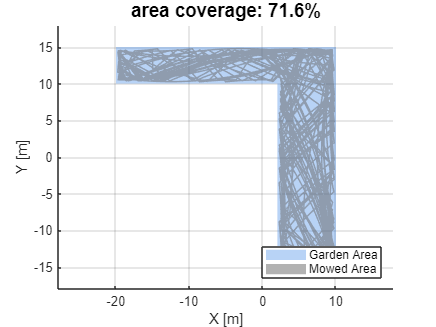

axis equal;
grid on;

% Gruppe C:
% function [] = computeMowingEfficiency(garden, path, width, reduction_factor, plot_result)
% computeMowingEfficiency calculates how efficiently a robot mows a garden
% and reports when 90% efficiency is reached (if ever).
%
% Inputs:
%   garden           - polyshape of the garden
%   path             - [n x 2] robot path (x,y)
%   width            - mowing width (default: 0.2 m)
%   reduction_factor - reduce number of path points (default: 5)
%   plot_result      - true/false to show final plot (default: true)


% prepare sinal list and names for the effeciency
ts = out.logsout{1}.Values;
x = ts.Data(:,1);
y = ts.Data(:,2);
path = [x, y];

% garden area
garden_shape = garden;

% just use points within garden
in_garden = isinterior(garden_shape, x, y);
path_in = path(in_garden, :);

% prepare signal list and names for coil outside garden
signals = {out.logsout{4}, out.logsout{6}, out.logsout{8}};
names = {'leftCoilInside', 'rearCoilInside', 'rightCoilInside'};


% computeMowingEfficiency(garden, path_in, 0.2, 40);

garden = garden;
path = path_in;
width = 0.2;
reduction_factor = 40;
plot_result = true;

    % Keep only points inside the garden
    inside = isinterior(garden, path(:,1), path(:,2));
    path_in = path(inside, :);

    % Reduce path for speed
    if reduction_factor > 1 && size(path_in,1) >= reduction_factor
        path_in = path_in(1:reduction_factor:end, :);
    end

    garden_area = area(garden);
    reached_90 = false;
    N = size(path_in, 1);

    % Create a full buffer polygon only once
    try
        full_buffer = polybuffer(path_in, 'lines', width/2);
    catch
        warning('polybuffer failed for full path.');
        full_buffer = polyshape();
    end

    % Precompute intersected polygon once
    intersect_full = intersect(full_buffer, garden);
    total_area = area(intersect_full);

    % Early loop with subsampling to find 90%
    check_points = round(linspace(20, N, min(100, N))); % up to 100 checks max

    for i = check_points
        try
            partial_buf = polybuffer(path_in(1:i,:), 'lines', width/2);
            partial_int = intersect(partial_buf, garden);
            partial_area = area(partial_int);
            efficiency = partial_area / garden_area;
        catch
            continue; % skip invalid step
        end

        % commend following loop if you dont want to compute the time till
        % 90%...
        if ~reached_90 && efficiency >= 0.9
            fprintf('Efficiency reached 90%% at step %d of %d (%.2f%%)\n', ...
                    i, N, efficiency*100);
            reached_90 = true;
            break;  % early exit, stop loop
        end
    end

    % Print final result
    final_efficiency = total_area / garden_area;
    fprintf('Model: %s\n', model_name);

Model: task_gruppeC


    fprintf('stop_time: %.2f\n', stop_time);

stop_time: 6000.00


    fprintf('Final mowed area: %.2f m²\n', total_area);

Final mowed area: 250.75 m²


    fprintf('Garden area: %.2f m²\n', garden_area);

Garden area: 350.00 m²


    fprintf('Final mowing earea coverage: %.2f %%\n', final_efficiency * 100);

Final mowing earea coverage: 71.64 %


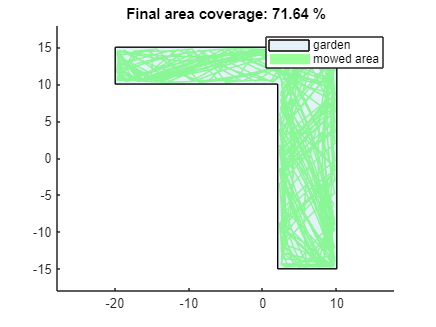


    % Plot final result
    if plot_result
        figure;
        plot(garden, 'FaceAlpha', 0.1); hold on;
        plot(intersect_full, 'FaceColor', 'green', 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        legend('garden', 'mowed area');
        title(sprintf('Final area coverage: %.2f %%', final_efficiency*100));
        axis equal;
    end